## 实验二 图像的灰度变换

1. 读取原图并显示

在这一步中，若原图不是单通道灰度图，则进行转换

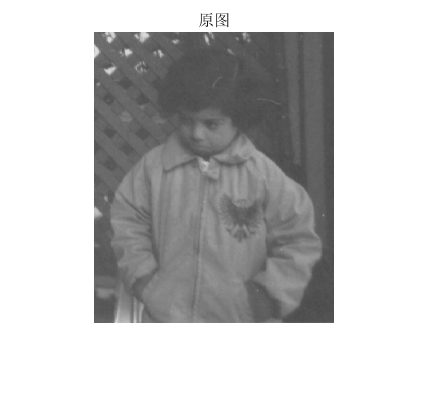

img_in = imread("pout.tif");
% 若为彩色图，则先转为灰度图像
if length(size(img_in)) > 2
    img_in= rgb2gray(img_in);
end
origin = im2double(img_in);
figure('Name','原图','NumberTitle','off');
imshow(origin);
title('原图');

2. 线性变换

MATLAB的imadjust函数默认会对所有像素值中最低的1%和最高的1%进行饱和处理

其中的 stretchlim 默认会找出占了1%到99%的颜色值

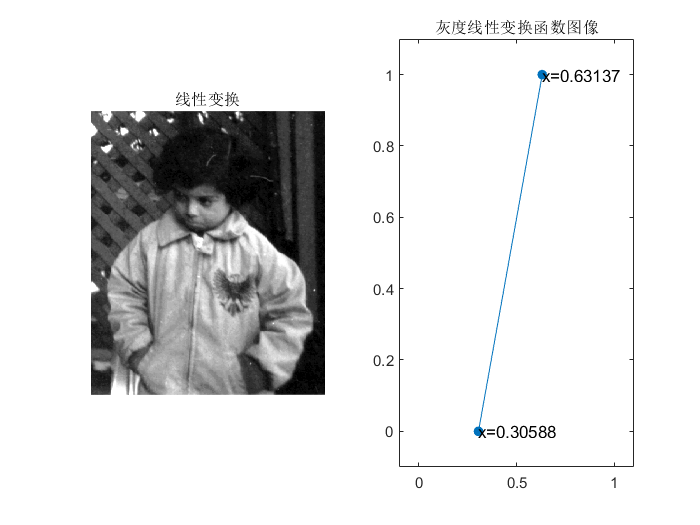

% 相当于 imadjust(origin, stretchlim(origin), [0 1])
linear_adj = imadjust(origin);
figure('Name','线性变换','NumberTitle','off');
subplot(1, 2, 1);
imshow(linear_adj);
title("线性变换")

% 此处绘制线性变换的函数图像
tmp = stretchlim(origin);
a = tmp(1); b = tmp(2);
c = 0; d = 1;
subplot(1, 2, 2);
plot([a b], [c d], '.-', 'MarkerSize', 20);
text(a, c, ['x=', num2str(a)]); text(b, d, ['x=', num2str(b)]);
xlim([-0.1 1.1]); ylim([-0.1 1.1]);
title("灰度线性变换函数图像");

3. 分段线性变换

(1) 只关注感兴趣部分，**不关注**其他部分

小于a的直接赋为c，大于b的直接赋为d

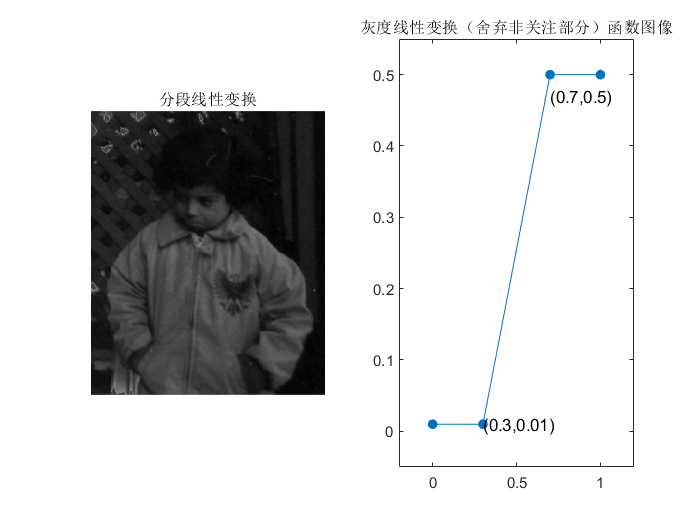

a = 0.3; b = 0.7;
c = 0.01; d = 0.5;
% 斜率为k
k = (d-c)/(b-a);
fenduan = origin;
% 小于a的直接赋为c
fenduan(fenduan<a) = c;
% 大于b的直接赋为d
fenduan(fenduan>b) = d;
% 中间部分正常线性变换
fenduan(fenduan>=a & fenduan<=b) = k*(fenduan(fenduan>=a & fenduan<=b)-a)+c;

figure('Name','分段线性变换','NumberTitle','off');
subplot(1, 2, 1);
imshow(fenduan);
title("分段线性变换");

% 绘制第一种分段线性变换的函数
subplot(1, 2, 2);
plot([0 a b 1], [c c d d], '.-', 'MarkerSize', 20);
xlim([-0.2 1.2]); ylim([-0.05 0.55]);
text(a, c, ['(', num2str(a), ',', num2str(c), ')']);
text(b, d-0.03, ['(', num2str(b), ',', num2str(d), ')']);
title("灰度线性变换（舍弃非关注部分）函数图像");

(2) 只关注感兴趣部分，**压缩**其他部分

与上面一种分段线性变换方法类似，区别在于[0, a)与(b, M]区间不是直接变换为一固定值，而是进行线性变换

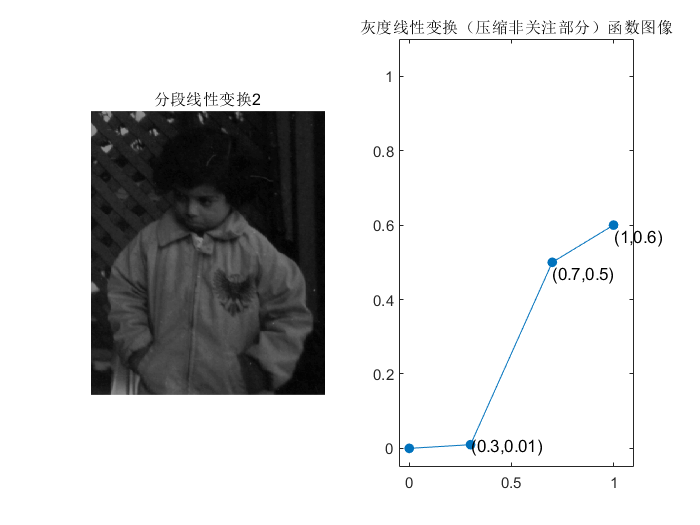

a = 0.3; b = 0.7;
c = 0.01; d = 0.5;
M = 1; N = 0.6;
% k1, k2, k3分别为三段线性变换的斜率
k1 = c / a; k2 = (d-c)/(b-a); k3 = (N-d)/(M-b);
fenduan2 = origin;
% 对三段分别进行线性变换
fenduan2(fenduan2<a & fenduan2>=0) = k1*fenduan2(fenduan2<a);
fenduan2(fenduan2>=a & fenduan2<=b) = k2*(fenduan2(fenduan2>=a & fenduan2<=b)-a)+c;
fenduan2(fenduan2>b & fenduan2<=M) = k3*(fenduan2(fenduan2>b & fenduan2<=M)-b)+d;

figure('Name','分段线性变换2','NumberTitle','off');
subplot(1, 2, 1);
imshow(fenduan2);
title("分段线性变换2");

% 绘制第二种分段线性变换的函数
subplot(1, 2, 2);
plot([0 a b M], [0 c d N], '.-', 'MarkerSize', 20);
xlim([-0.05 1.1]); ylim([-0.05 1.1]);
text(a, c, ['(', num2str(a), ',', num2str(c), ')']);
text(b, d-0.03, ['(', num2str(b), ',', num2str(d), ')']);
text(M, N-0.03, ['(', num2str(M), ',', num2str(N), ')']);
title("灰度线性变换（压缩非关注部分）函数图像");

4. 对数变换

使用换底公式完成任意底数的变换

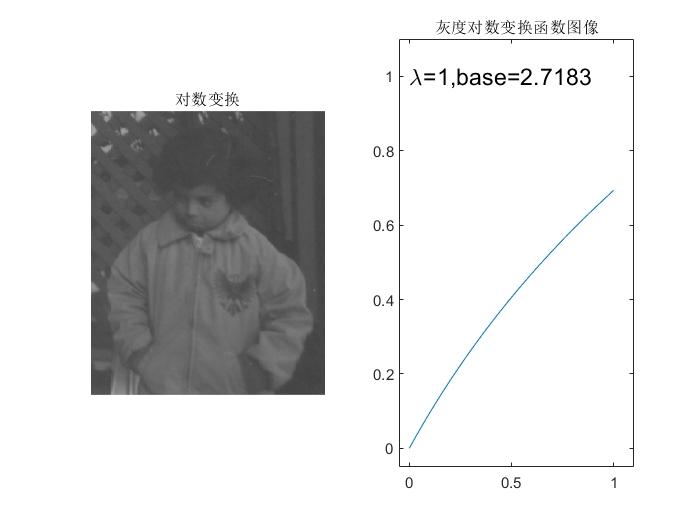

% base为对数变换的底数
lambda = 1; base = exp(1);

duishu = lambda*(log(1+origin)/log(base));
figure('Name','对数变换','NumberTitle','off');
subplot(1, 2, 1);
imshow(duishu);
title("对数变换");

% 绘制对数变换的函数图像
x = [0:0.01:1]; y = lambda*(log(1+x)/log(base));
subplot(1, 2, 2);
plot(x, y);
xlim([-0.05 1.1]); ylim([-0.05 1.1]);
text(0, 1, ['\lambda=' num2str(lambda) ',base=' num2str(base)], 'FontSize', 14);
title("灰度对数变换函数图像");

5. 指数变换

当γ＜1时会将原图像的灰度向高亮度部分映射，γ＞1时向低亮度部分映射

加入一个微小偏移量防止γ<1时底数等于0

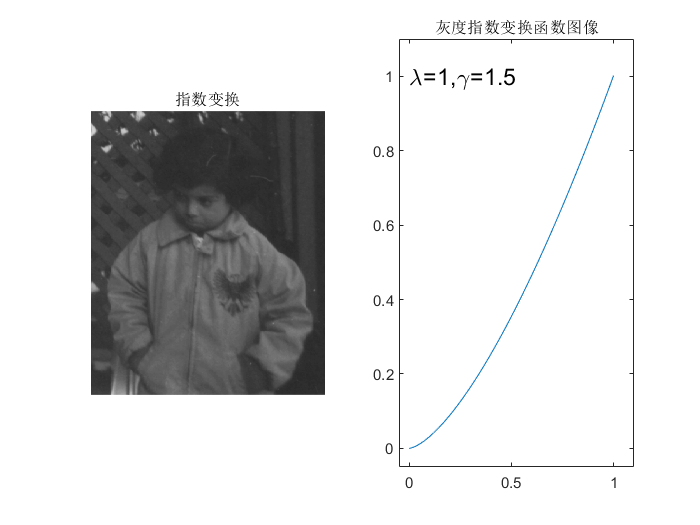

% gamma为指数
lambda = 1; gamma = 1.5;

zhishu = lambda*(origin+0.001).^gamma;
figure('Name','指数变换','NumberTitle','off');
subplot(1, 2, 1);
imshow(zhishu);
title("指数变换");

% 绘制指数变换的函数图像
x = [0:0.01:1]; y = lambda*(x+0.001).^gamma;
subplot(1, 2, 2);
plot(x, y);
xlim([-0.05 1.1]); ylim([-0.05 1.1]);
text(0, 1, ['\lambda=' num2str(lambda) ',\gamma=' num2str(gamma)], 'FontSize', 14);
title("灰度指数变换函数图像");

6. 直方图修正

(1) 使用MATLAB自带的 histeq 函数直接实现直方图修正

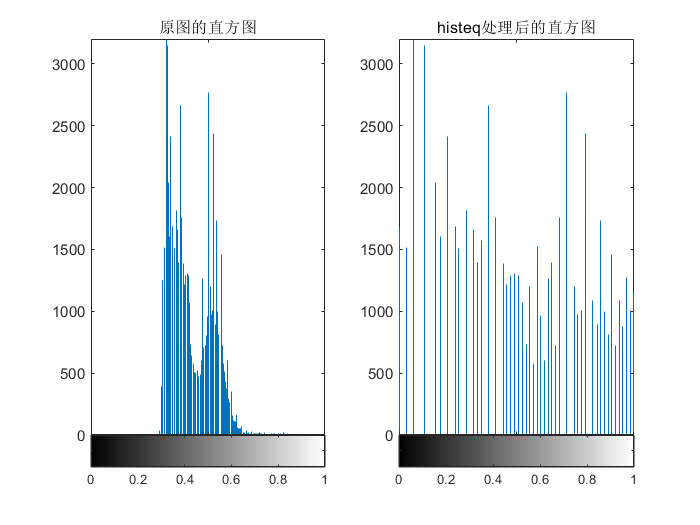

figure('Name','histeq直方图修正','NumberTitle','off');
% 先绘制原图的直方图，以便对比
subplot(1, 2, 1);
imhist(origin);
xlim([0 1]); ylim([0 3200])
title('原图的直方图');

hist = histeq(origin);
subplot(1, 2, 2);
imhist(hist);
xlim([0 1]); ylim([0 3200])
    title('histeq处理后的直方图');

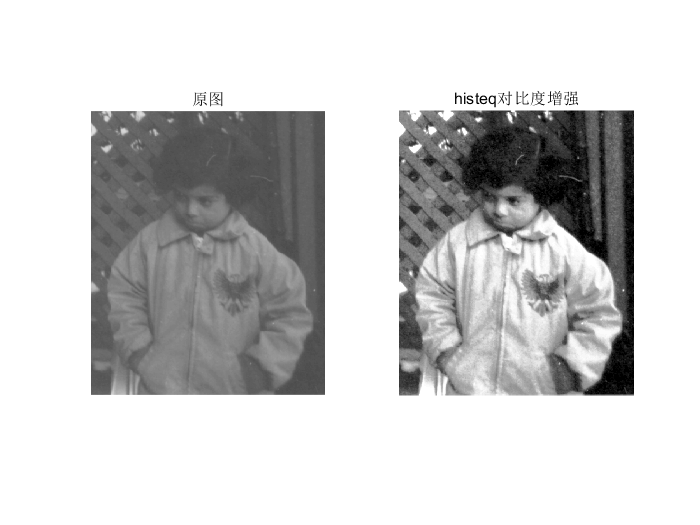


% 显示原图与增强后的图像进行对比
figure('Name','histeq对比度增强展示','NumberTitle','off');
subplot(1, 2, 1);
imshow(origin);
title('原图');
subplot(1, 2, 2);
imshow(hist);
title('histeq对比度增强');

(2) 自己编写代码实现直方图修正

**STEP1：统计原图像各灰度级像素个数**

此处默认灰度等级为256级

% 获得图片的宽高
[height, width] = size(img_in);
% n 用于统计各灰度值像素的个数，实际灰度为下标减一
n = zeros(1, 256);
for i=0:255
    n(i+1) = length(find(img_in==i));
end

**STEP2：计算原始直方图**

% 除以像素总数即可
p = n/(width*height);

**STEP3：计算累积直方图**

s = zeros(1, 256);
s(1) = p(1);
% 递推计算，可以少一层循环
for i=2:256
    s(i) = p(i)+s(i-1);
end

**STEP4：计算变换后的灰度值**

% 先把累积概率乘上255，同时四舍五入
s2 = round(s*255);

**STEP5：确定灰度变换关系**

在这一步中同时对图像进行重新映射，s(i) 对应到 s2(i) 中

% 直接更新原图像（未归一化的）
self_hist = img_in;
% 将原图逐个灰度等级进行映射
for i=0:255
    self_hist(img_in==i) = s2(i+1);
end

% 重新统计修正后的直方图
n2 = zeros(1, 256);
for i=0:255
    n2(i+1) = length(find(self_hist==i));
end
p2 = n2/(width*height);

**最后将结果进行绘制与显示**

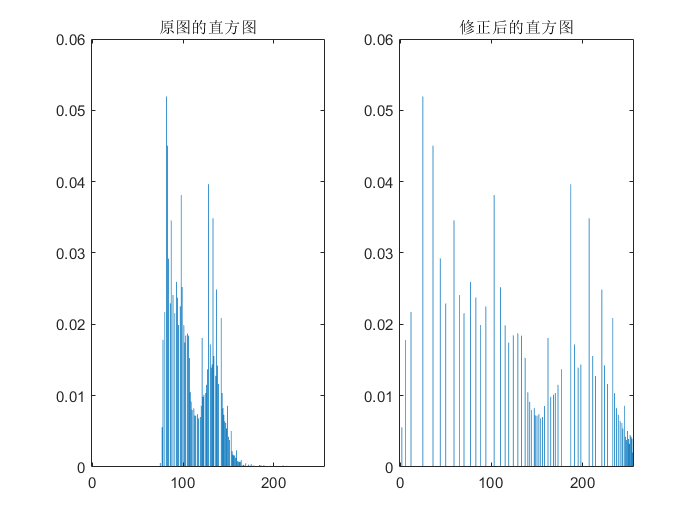

figure('Name','自己实现的直方图修正','NumberTitle','off');
% 先绘制原图的直方图，以便对比
subplot(1, 2, 1);
bar([0:255], p);
title('原图的直方图');

subplot(1, 2, 2);
bar([0:255], p2);
title('修正后的直方图');

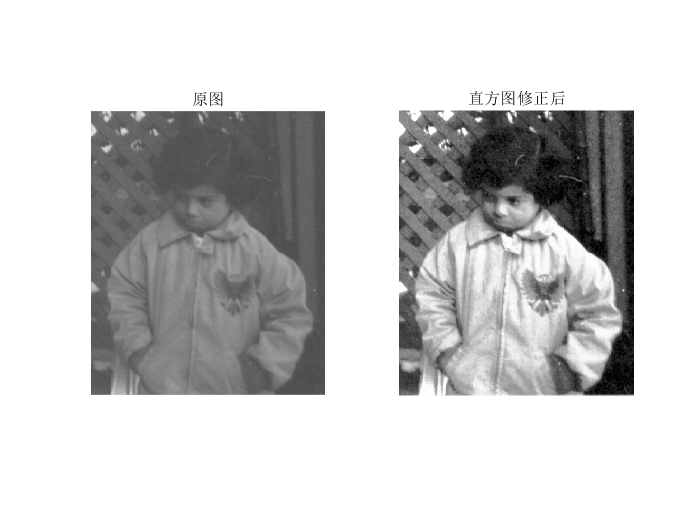


figure('Name','自己实现的对比度增强展示','NumberTitle','off');
subplot(1, 2, 1);
imshow(origin);
title('原图');

subplot(1, 2, 2);
imshow(self_hist);
title('直方图修正后');

7. 全部处理后图像的对比

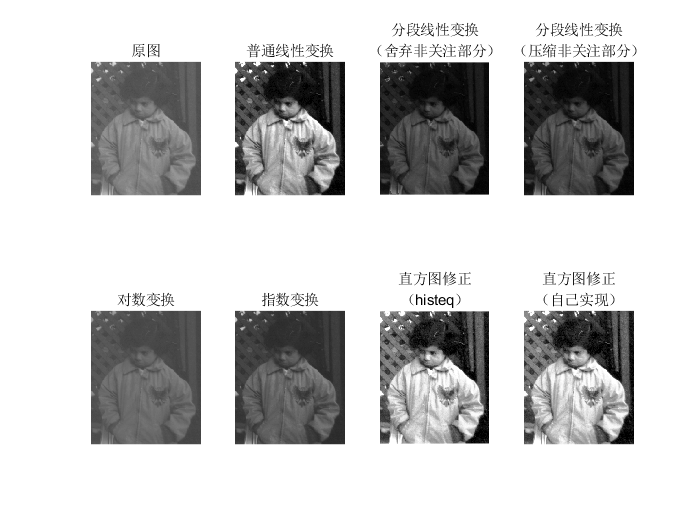

figure('Name','所有处理后图像对比','NumberTitle','off');
subplot(2, 4, 1); imshow(origin); title('原图')
subplot(2, 4, 2); imshow(linear_adj); title('普通线性变换');
subplot(2, 4, 3); imshow(fenduan); title({'分段线性变换','（舍弃非关注部分）'});
subplot(2, 4, 4); imshow(fenduan2); title({'分段线性变换','（压缩非关注部分）'});
subplot(2, 4, 5); imshow(duishu); title('对数变换');
subplot(2, 4, 6); imshow(zhishu); title('指数变换');
subplot(2, 4, 7); imshow(hist); title({'直方图修正','（histeq）'});
subplot(2, 4, 8); imshow(hist); title({'直方图修正','（自己实现）'});